# Momentum storage capabilities

*By Ricardo Colpari*

Failure to pass the axis of action of the force exerted by the thruster during the maneuver can cause a disturbing moment. Therefore the center of mass must remain as close as possible to the axis of action of the thruster. In this script this problem is described, and the limits of the misalignment are explained.

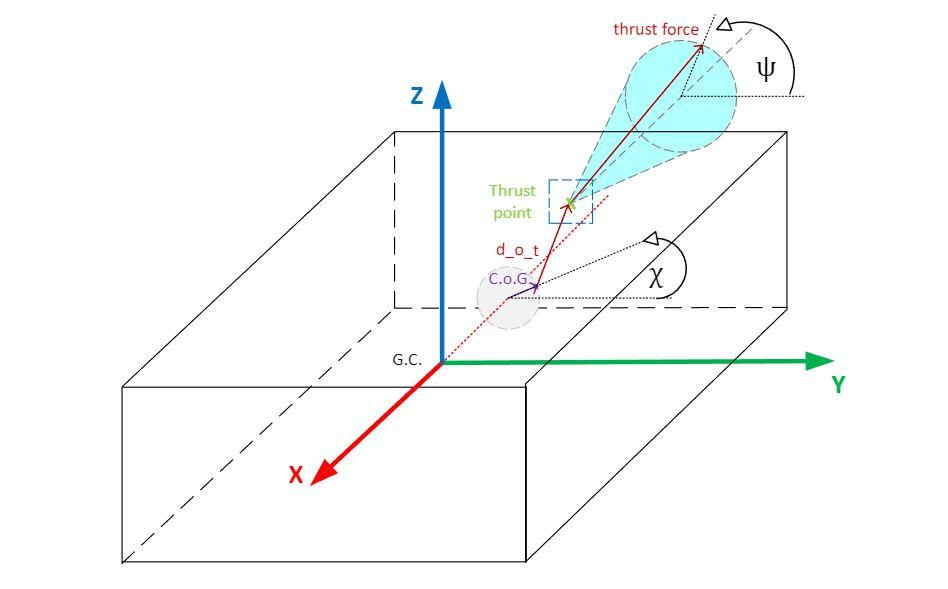

The figure shows the satellite in the Body Reference Frame (BRF). Let us note G.C. as the geometric center, or $GC=[0,0,0]$, it is the origin of the BRF.

The Center of Gravity (C.o.G.) coordinates of the satellite might not coincide with the GC, $CoG=[x_{CoG} , y_{CoG} , z_{CoG} ]$.

The thruster produces a force at a point $T=[x_{th} , y_{th} , z_{th} ]$

The thrust force is expected to be aligned with the CoG, otherwise, there is a resultant torque when the force of the thrust is exerted, and the thruster is designed to be aligned with the GC, therefore, the difference between CoG and GC will cause a torque, furthermore, there is a deviation in the direction of the thrust, this deviation could increase the effect of the disturbance torque.

## Calculation with variation of two angles and x_CoG=0

First, we input some constants, such as the deviation angle of the thruster, which has a tolerance of ±1°, and the duration of the thrust, which is considered to be 50 minutes. For this, a vector on the XY plane is created, this will represent the thrust F. Also the position of points T and CoG will be defined here. T has a tolerance of ±1mm. CoG as far away as possible from T is the worst case.

%% now varying two angles ψ, χ
clear
dev=pi/180;                         %deviation in rads of the thruster wrt to x axis, this is the initial in plane xy
Time= 50 * 60;                      %time of thrust in seconds (50 minutes)
                                    %the deviation is of dev=1 degree
F=0.75*[cos(dev);sin(dev);0]*1e-3;  %F in [N] 
%position of points T & CoG
x_th=183;       %Position x of point of thrust
y_th=0;         %Position y of point of thrust
z_th=0;         %Position z of point of thrust
x_cog=0;        %Distance of CoG from the geometric center x axis in mm
% y_cog=3.81;     %Distance of CoG from the geometric center y axis in mm
% z_cog=8.23;     %Distance of CoG from the geometric center z axis in mm

%D=[x_th-x_cog;y_th-y_cog;z_th-z_cog]/1e3;    %Distance from the geometric center in m

This deviation is of 1° in any direction, so, the force F will be rotated around BRF X axis to cover all possibilities, the angle of rotation around X axis is called ψ, its values range from 0° to 360° $\psi=[0,360]$.

Only the position of x_CoG was fixed, let's find the values of r, y_CoG and z_CoG based on a value of the angle χ, 

$r=\sqrt{y_{CoG}^2+z_{CoG}^2}$, 


$$cos(\chi)=y_{CoG}/r$$


therefore, this angle is defined to be zero, when $y_{CoG}=r$ and $z_{CoG}=0$, when χ is 90°, then $y_{CoG}=0$ and $z_{CoG}=r$ and so on.

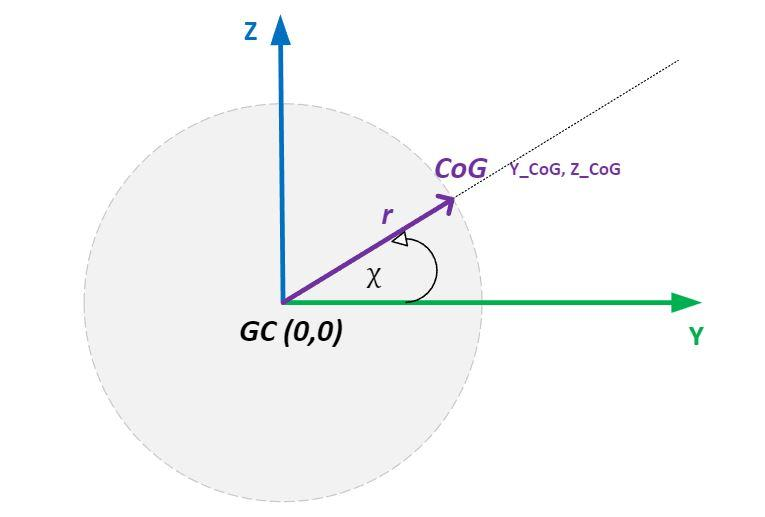

In this case, r is asigned a value of 1cm

% ψ is the rotation of a degrees of the force around X axis 
% χ is the rotation of b degrees of the force around X axis 
step_angle=1;
a=0;
F_rot=[0;0;0];      %initialize F_rot
%MMS=[0;0;0];       %initialize variables
r=10;               %radius of circle around YZ plane where the CoG lies [mm]

The misalignment torque can be calculated as:


$$\tau=F \times d=F \times (T-CoG)$$


The required momentum storage is the torque multiplied by the time it is applied, that is to say:


$$\textrm {Maximum Momentum Storage}=MMS=F \cdot t_{thrust}$$


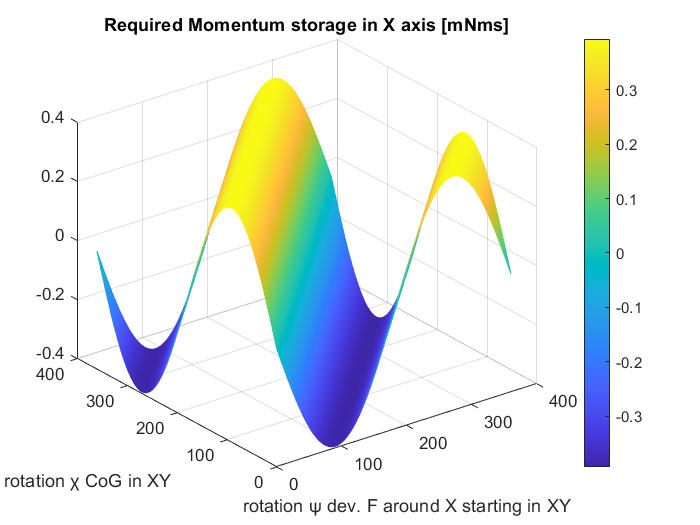

for j=1:360/step_angle+1
    beta=step_angle*(j-1)*pi/180;
    b(j)=beta*180/pi;
    y_cog=r*cos(beta);
    z_cog=r*sin(beta);
    D=[x_th-x_cog;y_th-y_cog;z_th-z_cog]/1e3;    %Distance from the geometric center in m
    
    for i=1:360/step_angle+1    %rotate F around x axis
        alpha=step_angle*(i-1)*pi/180;
        a(i)=alpha*180/pi;
        R=[ 1    0            0;...
            0    cos(alpha)  -sin(alpha);...
            0    sin(alpha)   cos(alpha)];
        F_rot(:,i)=R*F;
        %MMS(i,j,:)=cross(F_rot(:,i),D)*1e3*Time;
        Mom_vec=cross(F_rot(:,i),D)*1e3*Time;   %momentum storage in mNms
        Mom_norm=norm(Mom_vec);
        MMS(i,j,1:3)=Mom_vec;
        MMS(i,j,4)=Mom_norm;
    end
end

%now to plot momentum storage
MMSx=MMS(:,:,1);
MMSy=MMS(:,:,2);
MMSz=MMS(:,:,3);
MMSnorm=MMS(:,:,4);

figure()
set(gcf,'color','w');
        mesh(a,b,MMSx);
        ylabel('rotation χ CoG in XY')
        xlabel('rotation ψ dev. F around X starting in XY')
        grid on
        title('Required Momentum storage in X axis [mNms]') 
        colorbar

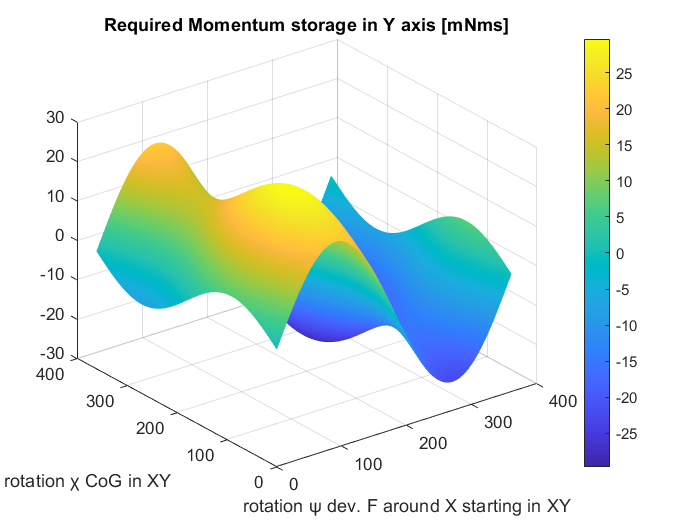

figure()
set(gcf,'color','w');
        mesh(a,b,MMSy);
        ylabel('rotation χ CoG in XY')
        xlabel('rotation ψ dev. F around X starting in XY')
        grid on
        title('Required Momentum storage in Y axis [mNms]')   
        colorbar

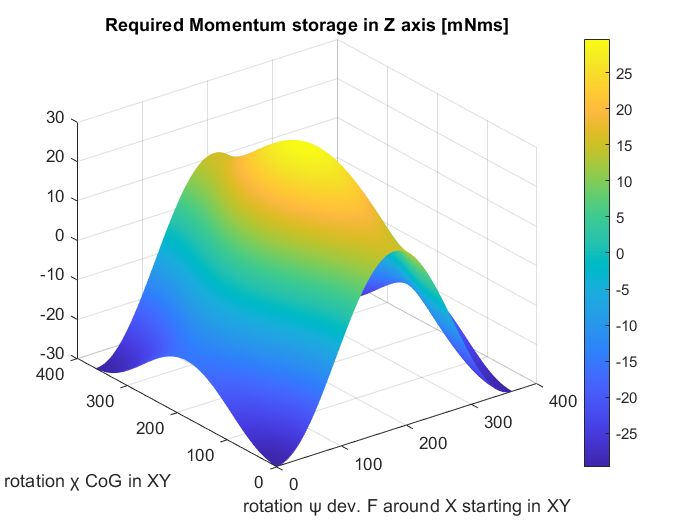

figure()
set(gcf,'color','w');
        mesh(a,b,MMSz);
        ylabel('rotation χ CoG in XY')
        xlabel('rotation ψ dev. F around X starting in XY')
        grid on
        title('Required Momentum storage in Z axis [mNms]')   
        colorbar

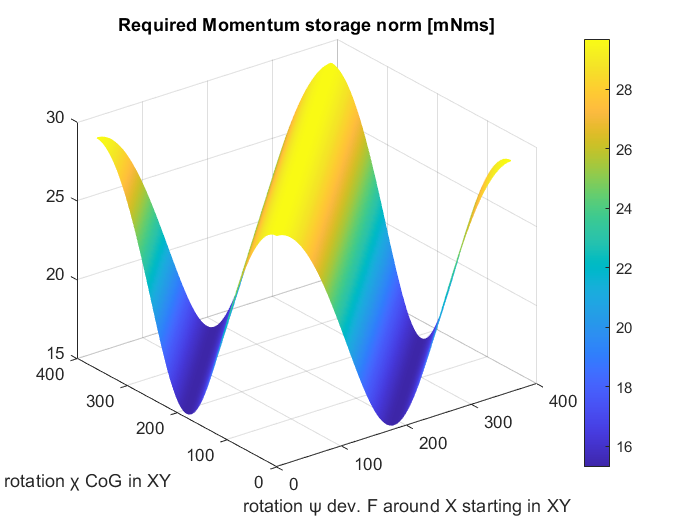

figure()
set(gcf,'color','w');
        mesh(a,b,MMSnorm);
        ylabel('rotation χ CoG in XY')
        xlabel('rotation ψ dev. F around X starting in XY')
        grid on
        title('Required Momentum storage norm [mNms]') 
        colorbar

From the plots above, we can see that the MMS in x direction is less than in the other directions, we can calculate the values with:

max (MMSx,[],'all')        

ans = 0.3927

max (MMSy,[],'all')        

ans = 29.6826

max (MMSz,[],'all')

ans = 29.6826

max (MMSnorm,[],'all')

ans = 29.6826

We can see that the value for MMS in x direction is much smaller than the other ones, the norm of the MMS is 29.68 mNms, if we compare it with the Maximum Momentum Storage of the Reaction Wheel Assembly (RWA), it is larger than that, so, if r=10mm, the momentum storage is insufficient in the worst case scenario for certain values of ψ, χ.

## Estimation of the maximum "r" with x_CoG=0

We know that MMS for each wheel is $MMS_{1-wheel}=16.2 mNms$,for the RWA, the maximum MMS in all three axis is:  1.79*16.2=28.998 mNms in each axis.

Taking a 10% margin in each axis: $MMS_{ each\ axis\ RWA}=26.09 mNms$ 

This is achieved with r<8.4mm, we can round down to r=8mm.

Then substracting the 1mm of error in T position (remember $T=[x_{th} , y_{th} , z_{th} ]\pm[0,1,1]$), a conservative value of r is **r = 7mm**. This is the maximum distance of the CoG from the Geometric Center in the Y-Z plane, assuming $x_{CoG}=0$.

r=8.4;            %radius of circle around YZ plane where the CoG lies
for j=1:360/step_angle+1
    beta=step_angle*(j-1)*pi/180;
    b(j)=beta*180/pi;
    y_cog=r*cos(beta);
    z_cog=r*sin(beta);
    D=[x_th-x_cog;y_th-y_cog;z_th-z_cog]/1e3;    %Distance from the geometric center in m    
    for i=1:360/step_angle+1    %rotate F around x axis
        alpha=step_angle*(i-1)*pi/180;
        a(i)=alpha*180/pi;
        R=[ 1    0            0;...
            0    cos(alpha)  -sin(alpha);...
            0    sin(alpha)   cos(alpha)];
        F_rot(:,i)=R*F;
        Mom_vec=cross(F_rot(:,i),D)*1e3*Time;   %momentum storage in mNms
        Mom_norm=norm(Mom_vec);
        MMS(i,j,1:3)=Mom_vec;
        MMS(i,j,4)=Mom_norm;
    end
end
%now to plot momentum storage
MMSx=MMS(:,:,1);
MMSy=MMS(:,:,2);
MMSz=MMS(:,:,3);
MMSnorm=MMS(:,:,4);
max (MMSnorm,[],'all')

ans = 26.0831

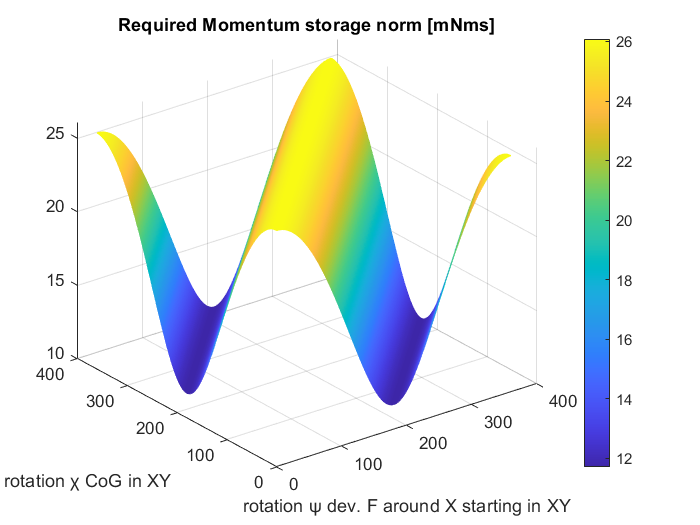

figure()
set(gcf,'color','w');
        mesh(a,b,MMSnorm);
        ylabel('rotation χ CoG in XY')
        xlabel('rotation ψ dev. F around X starting in XY')
        grid on
        title('Required Momentum storage norm [mNms]') 
        colorbar

If $x_{CoG}>0$, the required Maximum momentum storage will decrease, this is if the CoG of the satellite is towards the "Back" of the satellite where the thruster is located. if $x_{CoG}<0$, the required Maximum momentum storage will increase. Therefore, it is desired to keep the CoG as close to the thruster as possible, always reminding the other requirements imposed by the CubeSat standard.